# Example 6.1

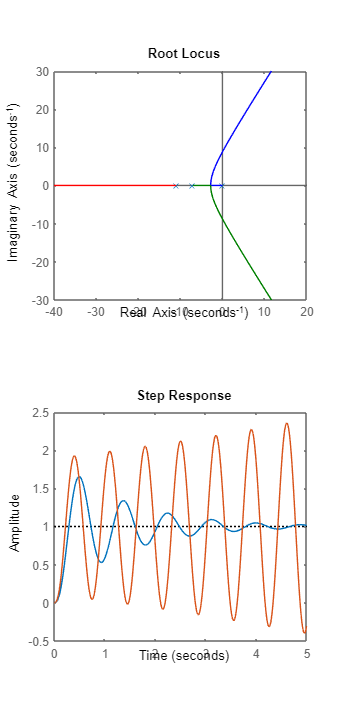

clc;
clear all;
clf;
s = tf('s');
G = 1/(s*(s+7)*(s+11));
f = figure;                
f.Position = [100, 100,400,850];
subplot(2,1,1)
rlocus(G)
subplot(2,1,2)
K = 860;
step(feedback(K*G,1),5)
hold on;
K = 1460;
step(feedback(K*G,1),5)

## Example 6.2

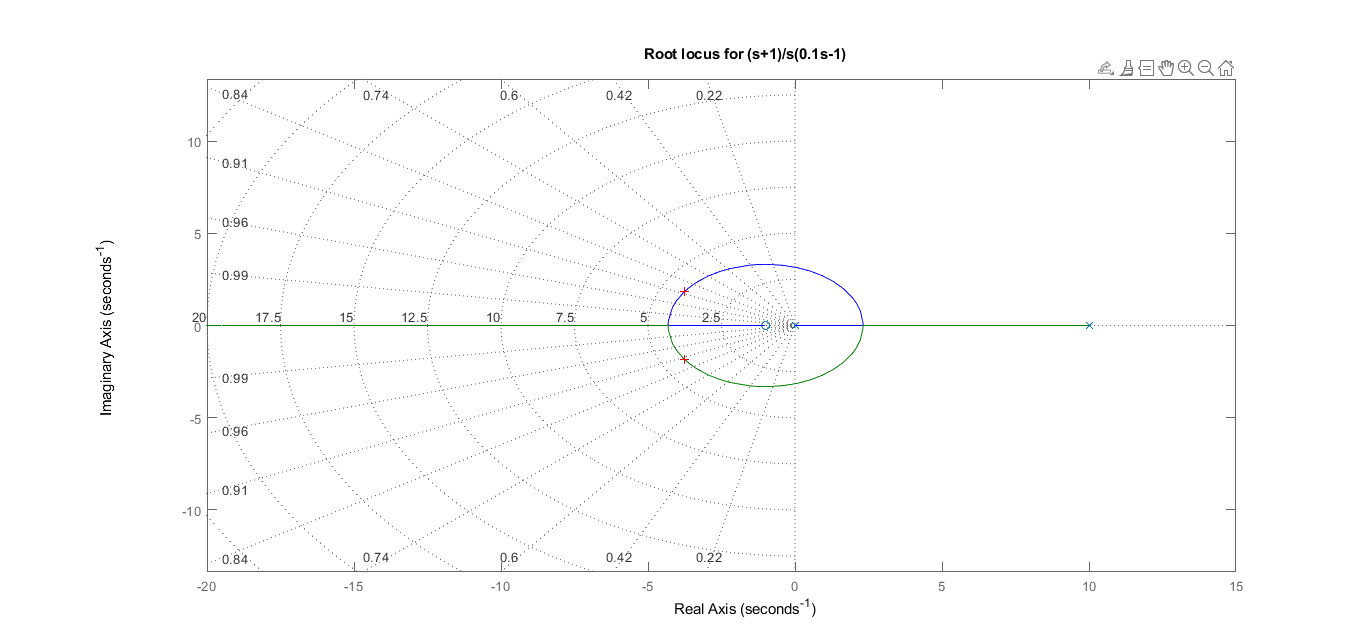

Select a point in the graphics window


selected_point = -3.7925 + 1.8435i

clc;
clear all;
clf;
s = tf('s');
G = (s+1)/(s*(0.1*s-1));
figure;                     
rlocus(G);
axis equal;
sgrid;
title('Root locus for (s+1)/s(0.1s-1)');
[K,p] = rlocfind(G); %choose a random point from graph.

figure;

## Example 6.3

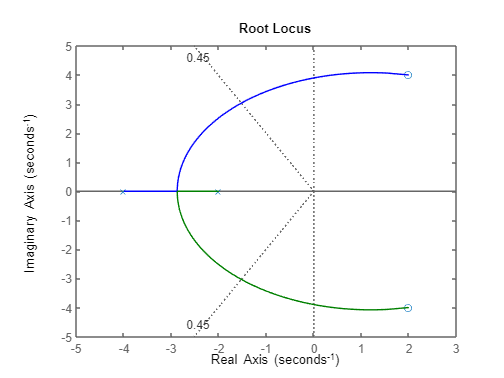

clc;
clear all;
clf;
s = tf('s');
G = (s^2-4*s+20)/((s+2)*(s+4));
rlocus(G);
zeta = 0.45;
wn = 0;
sgrid(zeta,wn);